B. Compression et décompression

Calcul de l'erreur après compression et décompression : 

% Charger l'image
original_image = imread('Nature.bmp'); % Charger votre image ici

% Initialiser des vecteurs pour stocker les résultats
difference_error = zeros(1,25);
standard_error = zeros(1,25);
non_zero_coefficients = zeros(1,25);

% Parcourir les différents facteurs de quantification
for quantization_factor = 1:25
    quantization_factor
    % Compression de l'image
    main_compression(quantization_factor, 'Nature.bmp', 'Nature_compressed.jpg');
    % Décompression de l'image
    main_decompression('Nature_compressed.jpg', 'Nature_decompressed.bmp');
    
    decompressed_image = imread('Nature_decompressed.bmp');
    % Calcul de la différence entre l'image originale et celle décompressée
    difference = double(original_image) - double(decompressed_image);
    difference_error(quantization_factor) = mean(abs(difference(:))); % Erreur moyenne
    standard_error(quantization_factor) = std(abs(difference(:))); % Erreur standard
    
end

quantization_factor = 1

quantization_factor = 2

quantization_factor = 3

quantization_factor = 4

quantization_factor = 5

quantization_factor = 6

quantization_factor = 7

quantization_factor = 8

quantization_factor = 9

quantization_factor = 10

quantization_factor = 11

quantization_factor = 12

quantization_factor = 13

quantization_factor = 14

quantization_factor = 15

quantization_factor = 16

quantization_factor = 17

quantization_factor = 18

quantization_factor = 19

quantization_factor = 20

quantization_factor = 21

quantization_factor = 22

quantization_factor = 23

quantization_factor = 24

quantization_factor = 25

Calcul du nombre de non-zeros

im = lecture_image_bmp('Nature.bmp');
non_zero = zeros(1,25); % Initialisez le vecteur pour stocker les résultats pour chaque facteur de quantification et chaque canal de couleur (Rouge, Vert, Bleu)

for quantization_factor = 1:25
    quantization_factor
    M = conversion_frequentiel_spatial(im, quantization_factor); %Matrice DCT qualité i
    for channel = 1:3
        nb = sum(M(:) > 0); % Compter le nombre de coefficients DCT non nuls pour ce canal de couleur
        non_zero(quantization_factor) = nb + non_zero(quantization_factor); % Stocker le résultat dans le vecteur nonZ
    end
end

quantization_factor = 1

quantization_factor = 2

quantization_factor = 3

quantization_factor = 4

quantization_factor = 5

quantization_factor = 6

quantization_factor = 7

quantization_factor = 8

quantization_factor = 9

quantization_factor = 10

quantization_factor = 11

quantization_factor = 12

quantization_factor = 13

quantization_factor = 14

quantization_factor = 15

quantization_factor = 16

quantization_factor = 17

quantization_factor = 18

quantization_factor = 19

quantization_factor = 20

quantization_factor = 21

quantization_factor = 22

quantization_factor = 23

quantization_factor = 24

quantization_factor = 25

Plot des résultats

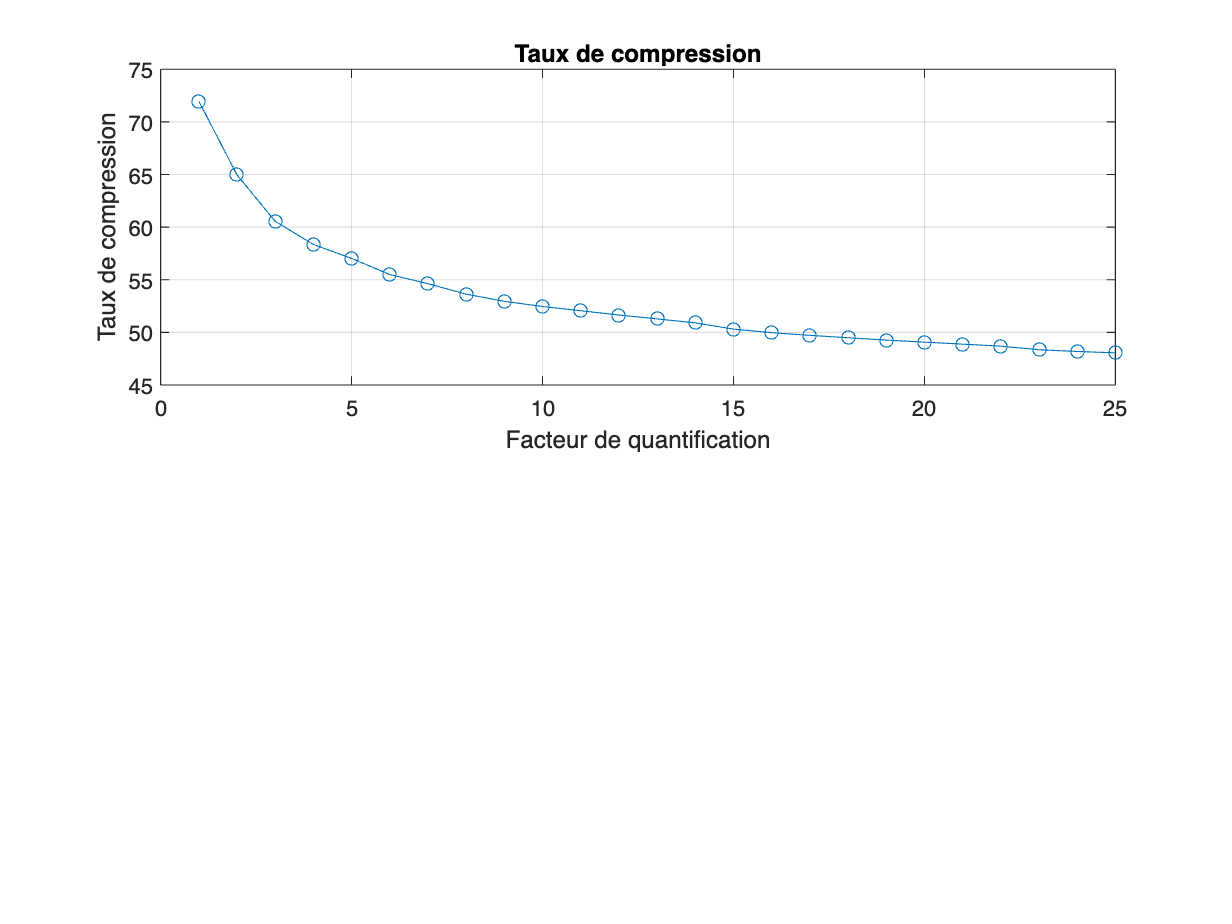

figure;
subplot(2,1,1);
plot(1:25, non_zero/(640*1024)*10, '-o');
title('Taux de compression');
xlabel('Facteur de quantification');
ylabel('Taux de compression');
grid on;

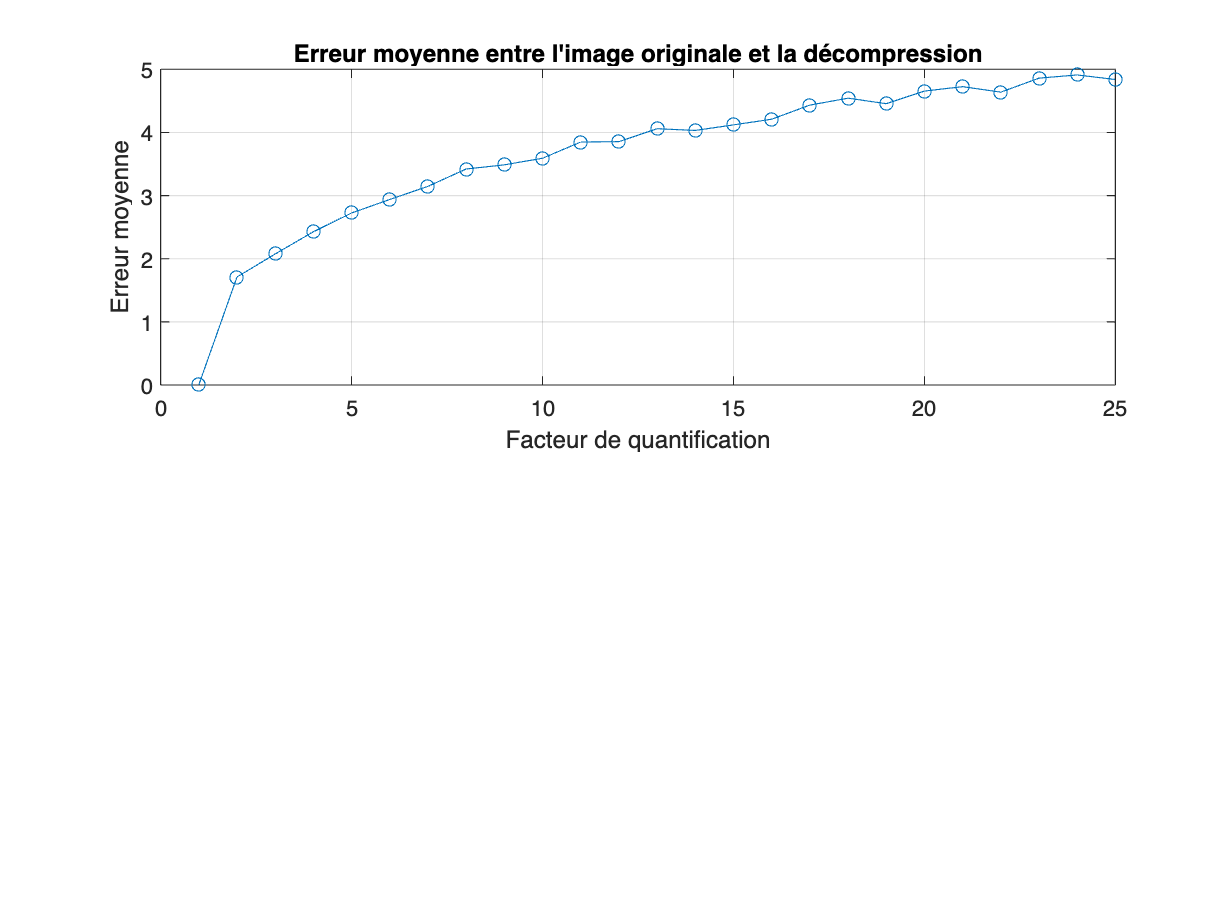


figure;
subplot(2,1,1);
plot(1:25, difference_error, '-o');
title('Erreur moyenne entre l''image originale et la décompression');
xlabel('Facteur de quantification');
ylabel('Erreur moyenne');
grid on;

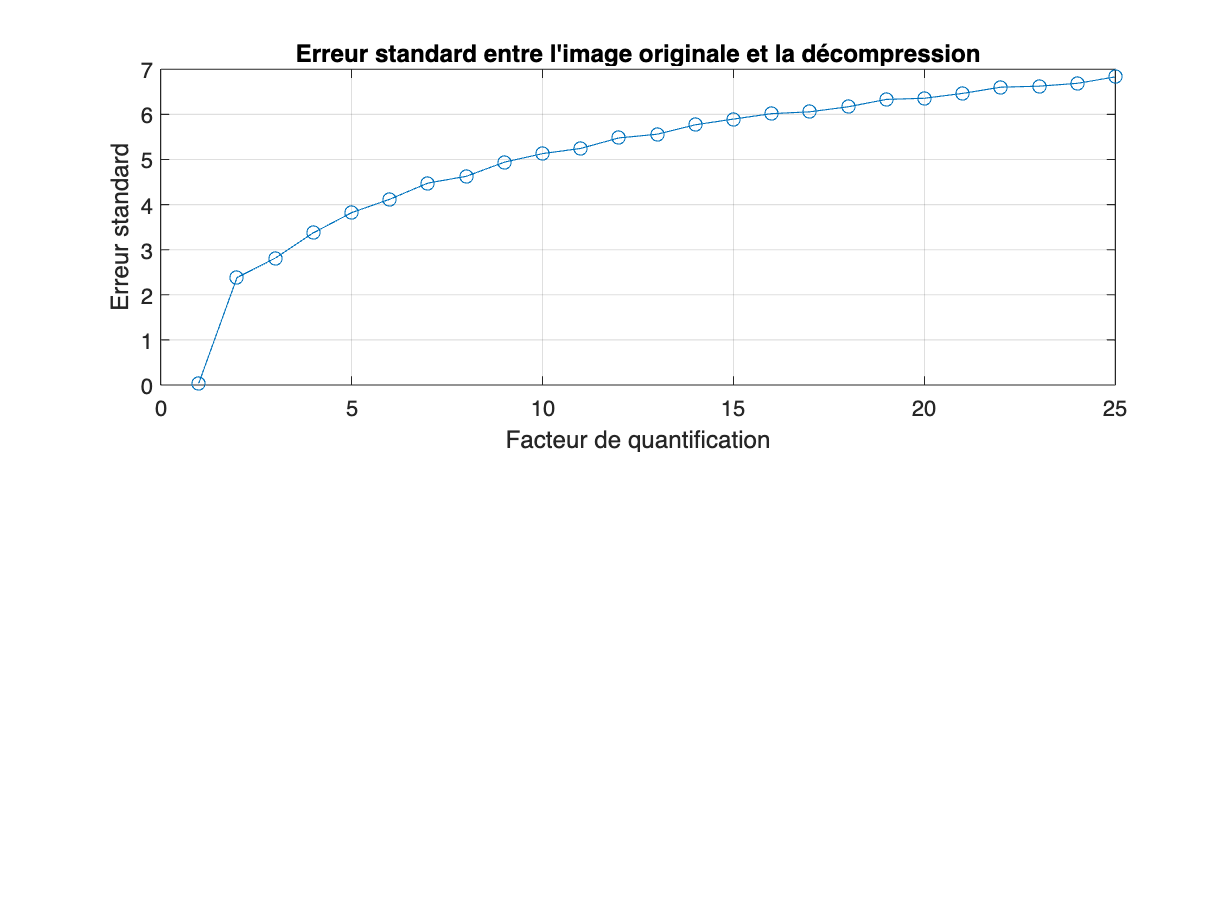

figure;
subplot(2,1,1);
plot(1:25, standard_error, '-o');
title('Erreur standard entre l''image originale et la décompression');
xlabel('Facteur de quantification');
ylabel('Erreur standard');
grid on;

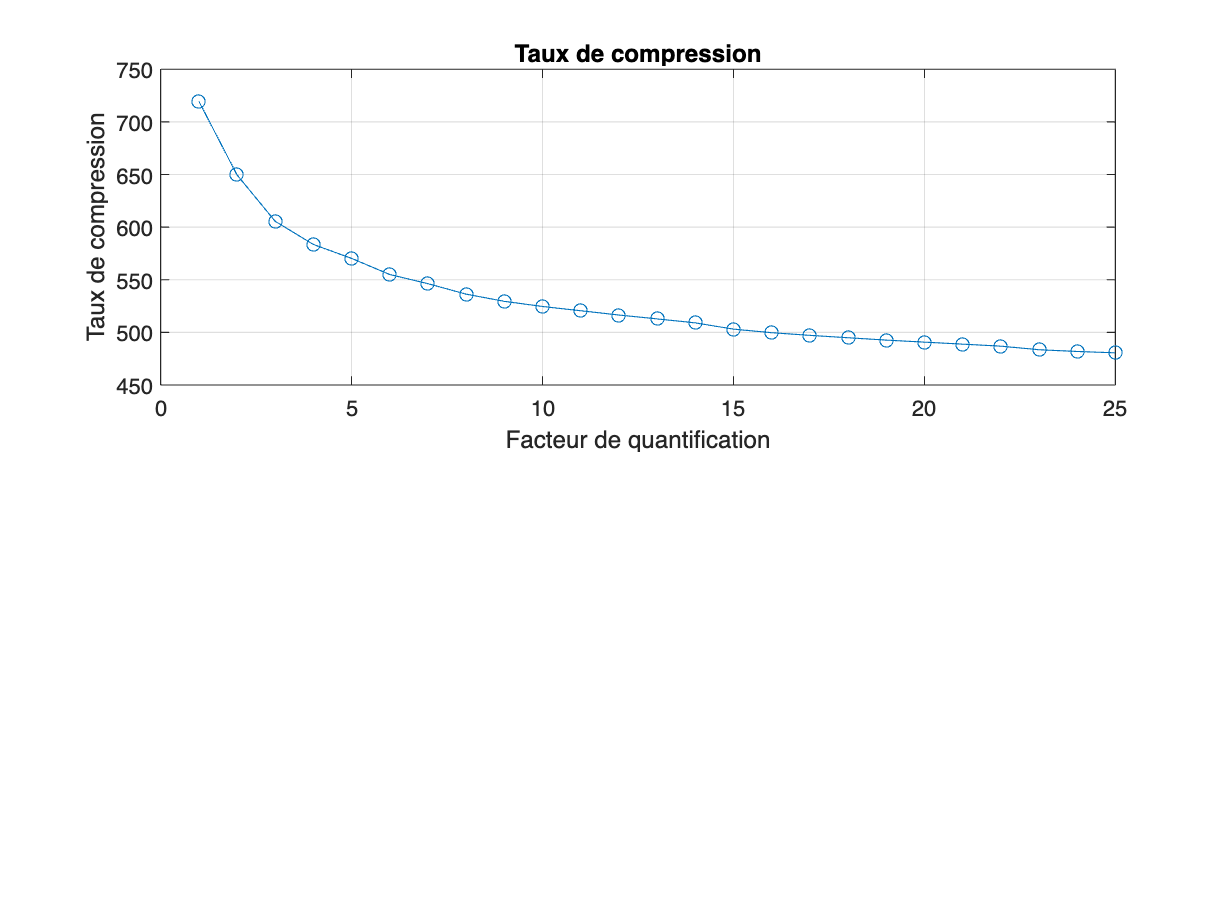


figure;
subplot(2,1,1);
plot(1:25, non_zero/(640*1024)*100, '-o');
title('Taux de compression');
xlabel('Facteur de quantification');
ylabel('Taux de compression');
grid on;